clear all
kp = 10e5 ;
kd = 10e2 ;
ki = 5*10e6 ;

a = 2;

A1 = [0 1 0;
    -kp -kd 1;
    -a*ki 0 0];
A2 = [0 1 0;
    -kp -kd 1;
    -ki 0 0];
eig(A1)

ans = 1.0e+02 *

  -4.4453 + 8.3890i
  -4.4453 - 8.3890i
  -1.1094 + 0.0000i


eig(A2)

ans = 1.0e+02 *

  -4.7369 + 8.5192i
  -4.7369 - 8.5192i
  -0.5262 + 0.0000i


Q = 0.5 * [0 1 0;
    1 0 0;
    0 0 0]%condition = x'*Q*x>= 0

Q =          0    0.5000         0
    0.5000         0         0
         0         0         0



A1*A2 == A2*A1

ans = 3×3 logical array
   1   1   1
   0   1   1
   1   0   1


P1 = lyap(A1,eye(3))

P1 = 1.0e+07 *

    0.0000   -0.0000    0.0000
   -0.0000    0.0001    0.0111
    0.0000    0.0111    6.1111


P2 = lyap(A2,P1)

P2 = 1.0e+05 *

    0.0000   -0.0000    0.0000
   -0.0000    0.0000    0.0008
    0.0000    0.0008    5.5263



det(P2)

ans = 0.2496

eig(P2)

ans = 1.0e+05 *

    0.0000
    0.0000
    5.5263



det(A2 * P2 + P2*A2)

ans = 1.8667e+18

%regions
E1 = [1 0 0;
    0 1 0;
    0 0 1]

E1 =      1     0     0
     0     1     0
     0     0     1


E3 = - E1

E3 =     -1     0     0
     0    -1     0
     0     0    -1


%active region P2 
E2 = [-1 0 0;
    0 1 0;
    0 0 1];
E4 = -E2

E4 =      1     0     0
     0    -1     0
     0     0    -1



amin = 1.9;
amax = 2;
ii = 40; %number of steps

a = [amin:(amax-amin)/(ii-1):amax]

a =     1.9000    1.9026    1.9051    1.9077    1.9103    1.9128    1.9154    1.9179    1.9205    1.9231    1.9256    1.9282    1.9308    1.9333    1.9359    1.9385    1.9410    1.9436    1.9462    1.9487    1.9513    1.9538    1.9564    1.9590    1.9615    1.9641    1.9667    1.9692    1.9718    1.9744    1.9769    1.9795    1.9821    1.9846    1.9872    1.9897    1.9923    1.9949    1.9974    2.0000


gamma = zeros(1,length(a))

gamma =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


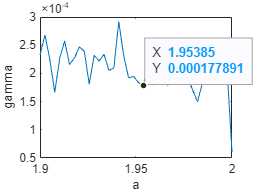

for i= 1:ii

A1 = [0 1 0;
    -kp -kd 1;
    -a(i)*ki 0 0];
A2 = [0 1 0;
    -kp -kd 1;
    -ki 0 0];


% To ensure continuity define Pi=Fi'*T*Fi
% To ensure continuity define Pi=Fi'*T*Fi
F1=[E1' eye(3)]';
F2=[E2' eye(3)]';
F3=[E3' eye(3)]';
F4=[E4' eye(3)]';

% LMI variables:
Tvar=sdpvar(6,6);
Uvar1=sdpvar(3,3);
Uvar2=sdpvar(3,3);
Uvar3=sdpvar(3,3);
Uvar4=sdpvar(3,3);

Wvar1=sdpvar(3,3);
Wvar2=sdpvar(3,3);
Wvar3=sdpvar(3,3);
Wvar4=sdpvar(3,3);

% Lyapunov condition:
Pvar1=F1'*Tvar*F1;
Pvar2=F2'*Tvar*F2;
Pvar3=F3'*Tvar*F3;
Pvar4=F4'*Tvar*F4;

%{
Lf1=[A1'*Pvar1+Pvar1*A1<=-1e-9];
Lf2=[A2'*Pvar2+Pvar2*A2<=-1e-9];
Lf3=[A1'*Pvar3+Pvar3*A1<=-1e-9];
Lf4=[A2'*Pvar4+Pvar4*A2<=-1e-9];


Lp1=[Pvar1>=1e-9];
Lp2=[Pvar2>=1e-9];
Lp3=[Pvar3>=1e-9];
Lp4=[Pvar4>=1e-9];
%}

%


%{
Lf1=[A1'*Pvar1+Pvar1*A1+E1'*Uvar1*E1<=-1e-9]; %question c
Lf2=[A2'*Pvar2+Pvar2*A2+E2'*Uvar2*E2<=-1e-9];
Lf3=[A1'*Pvar3+Pvar3*A1+E3'*Uvar3*E3<=-1e-9];
Lf4=[A2'*Pvar4+Pvar4*A2+E4'*Uvar4*E4<=-1e-9];
%}

%
K = [1 0 0; 0 0 0; 0 0 0];
B = [0; 1; 0];
Gvar = sdpvar(1,1);
Lf1=[K + A1'*Pvar1+Pvar1*A1+E1'*Uvar1*E1, Pvar1*B; B'*Pvar1, -Gvar]<=-1e-9; %question d
Lf2=[K + A2'*Pvar2+Pvar2*A2+E2'*Uvar2*E2, Pvar2*B; B'*Pvar2, -Gvar]<=-1e-9;
Lf3=[K + A1'*Pvar3+Pvar3*A1+E3'*Uvar3*E3, Pvar3*B; B'*Pvar3, -Gvar]<=-1e-9;
Lf4=[K + A2'*Pvar4+Pvar4*A2+E4'*Uvar4*E4, Pvar4*B; B'*Pvar4, -Gvar]<=-1e-9;
%}

Lp1=[Pvar1-E1'*Wvar1*E1>=1e-9];
Lp2=[Pvar2-E2'*Wvar2*E2>=1e-9];
Lp3=[Pvar3-E3'*Wvar3*E3>=1e-9];
Lp4=[Pvar4-E4'*Wvar4*E4>=1e-9];
%}

Lpos=[Gvar >= 1e-9, Uvar1(:)>=0, Uvar2(:)>=0, Uvar3(:)>=0, Uvar4(:)>=0, Wvar1(:)>=0, Wvar2(:)>=0, Wvar3(:)>=0, Wvar4(:)>=0];

L=Lf1+Lf2+Lf3+Lf4+Lp1+Lp2+Lp3+Lp4+Lpos;

%solve the LMI using SDPT3:
opts = sdpsettings('solver','sdpt3','verbose',0);
diagnostics = optimize(L,[],opts);

%retrieve the solutions:


gamma(i) = 1/sqrt(value(Gvar));
end
    
figure()
clf
plot(a,gamma)
hold on
xlabel('a')
ylabel('gamma')